# Gauss-Newton-Verfahren

Wir betrachten das nichtlineare Ausgleichsproblem aus Bespiel 6.1 (Buch):

           
$$\min_{x \in \mathbb{R}^4} \|F(x)\|_2,
$$


          
$$F_i(x):= x_1 e^{-x_2t_i} \sin(x_3 t_i +x_4) -b_i, ~~i=1,\ldots, 10,$$


mit den Werten $(t_i,b_i)$ aus Tabelle 6.1 (Buch). Diese Daten sind:

t=[0.1 0.3 0.7 1.2 1.6 2.2 2.7 3.1 3.5 3.9]';
b=[0.558 0.569 0.176 -0.207 -0.133 0.132 0.055 -0.090 -0.069 0.027]';

Als Startwert für das Gauss-Newton-Verfahren wählen wir

xold=[1, 2, 2, 1]';

In jedem Iterationsschritt des Gauss-Newton-Verfahrens werden folgende Größen angezeigt:

- NormF$=\|F(x^k)\|_2$

- err$=\|\nabla \phi(x^k)\|_2$   (siehe Buch)

- KonvFaktor$=\|\nabla \phi(x^k)\|_2/\|\nabla \phi (x^{k-1})\|_2 $

Als Stoppkriterium wird verwendet:  err $\leq 10^{-6}$ oder $k  \geq k_{\max}=20$.

Falls mit höchstens 20 Iterationen die vorgebene Toleranz erreicht wird, werden $k$ (Anzahl der Iterationen) und $x^k$ (berechnete optimale Parameterwerte) gezeigt.

Beachte, dass $F(x_1,x_2,x_3,x_4)=F(-x_1,x_2,x_3,x_4 \pm \pi)$gilt und deshalb mehrere lokale Minima mit gleichem Residuum existieren.

# Aktivität:

Ändern Sie den Startwert und beobachten Sie die Effekte auf das Konvergenzverhalten und die jeweils gefundene Lösung!

## Gauss-Newton-Verfahren:

k=0; kmax=20; epsilon=10^(-6);
err= 1;
Fvalue= F(xold,t,b);
A= DF(xold,t,b);
errold= norm(A'*Fvalue);
Erg= zeros(2,kmax+1);
Erg(:,1)= [errold; norm(Fvalue)];
while ((k < kmax) && (err > epsilon))
    s= A\(-Fvalue);  % lineares Ausgleichsproblem min_{s}\|As +Fvalue\|_2  wird gelöst
    xnew= xold+s;
    Fvalue= F(xnew,t,b);
    fprintf('\nIteration %u: \n',k+1);
    NormF= norm(Fvalue)
    A= DF(xnew,t,b);
    err= norm(A'*Fvalue)
    KonvFaktor= err/errold
    disp('----------------');   
    errold= err;
    xold= xnew;
    k=k+1;
    Erg(:,k+1)= [err; NormF];
end
visualizeIter(Erg,k);

if (err > epsilon)
    fprintf('\nToleranz nicht erreicht in 20 Iterationen \n');
else
    fprintf('\nToleranz erreicht nach k = %u Iterationen \n',k);
    fprintf('\nOptimale Parameterwerte: \n');
    result=xnew
    visualizeSol(xnew,t,b)
end;

 In der Funktion DF wird die Jacobi-Matrix bestimmt.

function [DFout]=DF(x,t,b)
    DFout=zeros(10,4);
    for i=1:10
        DFout(i,1)= exp(-x(2)*t(i))*sin(x(3)*t(i)+x(4));


Iteration 1: 


NormF = 0.3426

err = 0.1352

KonvFaktor = 0.9296

----------------



Iteration 2: 


NormF = 0.2227

err = 0.0487

KonvFaktor = 0.3605

----------------



Iteration 3: 


NormF = 0.1705

err = 0.1040

KonvFaktor = 2.1342

----------------



Iteration 4: 


NormF = 0.0921

err = 0.0186

KonvFaktor = 0.1789

----------------



Iteration 5: 


NormF = 0.0891

err = 0.0012

KonvFaktor = 0.0651

----------------



Iteration 6: 


NormF = 0.0890

err = 3.9385e-04

KonvFaktor = 0.3249

----------------



Iteration 7: 


NormF = 0.0890

err = 1.2024e-04

KonvFaktor = 0.3053

----------------



Iteration 8: 


NormF = 0.0890

err = 4.2424e-05

KonvFaktor = 0.3528

----------------



Iteration 9: 


NormF = 0.0890

err = 1.4384e-05

KonvFaktor = 0.3391

----------------



Iteration 10: 


NormF = 0.0890

err = 5.0556e-06

KonvFaktor = 0.3515

----------------



Iteration 11: 


NormF = 0.0890

err = 1.7491e-06

KonvFaktor = 0.3460

----------------



Iteration 12: 


NormF = 0.0890

err = 6.1105e-07

KonvFaktor = 0.3493

----------------


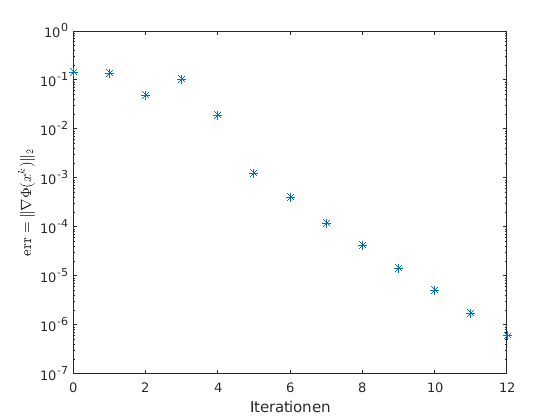

        DFout(i,2)= -x(1)*t(i)*exp(-x(2)*t(i))*sin(x(3)*t(i)+x(4));

        DFout(i,3)= x(1)*t(i)*exp(-x(2)*t(i))*cos(x(3)*t(i)+x(4));
        DFout(i,4)= x(1)*exp(-x(2)*t(i))*cos(x(3)*t(i)+x(4));
    end
end

In der Funktion F wird die Funktion  $F$ ausgewertet. 


Toleranz erreicht nach k = 12 Iterationen 



Optimale Parameterwerte: 


result =     0.7354
    0.7962
    3.0745
    0.6042


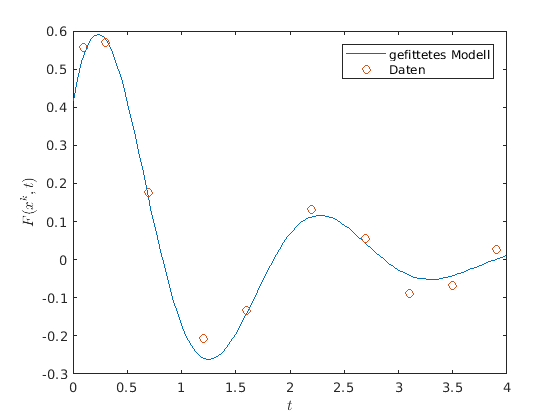

function [Fout]=F(x,t,b)
    Fout=zeros(10,1);
    for i=1:10
       Fout(i)=x(1)*exp(-x(2)*t(i))*sin(x(3)*t(i)+x(4))-b(i);
    end

end

Die Funktion `visualizeIter` plottet die Werte von err über die Iterationen $k$.

function visualizeIter(Erg,iter)
    semilogy(0:iter,Erg(1,1:iter+1),'*');
    xlabel('Iterationen');  ylabel('${\rm err}=\|\nabla \Phi(x^k)\|_2$','Interpreter','latex')
end

Die Funktion `visualizeSol` plottet das gefittete Modell $F(x^k)$ als Funktion vonn $t$ und die zugehörigen Daten $(t_i,b_i)$.

function visualizeSol(x,ti,bi)
    t=linspace(0,4);
    plot(t,x(1)*exp(-x(2).*t).*sin(x(3).*t+x(4)),ti,bi,'o');
    xlabel('$t$','Interpreter','latex');  ylabel('$F(x^k,t)$','Interpreter','latex')
    legend('gefittetes Modell','Daten')
end